# Nonlinear ARX Model of SI Engine Torque Dynamics

This example describes modeling the nonlinear torque dynamics of a spark-ignition (SI) engine as a nonlinear ARX model. The identified model can be used for hardware-in-the-loop (HIL) testing, powertrain control, diagnostic, and training algorithm design. For example, you can use the model for aftertreatment control and diagnostics algorithm development. For more information on nonlinear ARX models, see [Nonlinear ARX Models](docid:ident_ug#br7uewe).

You use measurements of the system inputs and outputs to identify the model. This data can come from measurements on a real engine or a high-fidelity model such as one created using the Powertrain Blockset™ SI Reference application. 

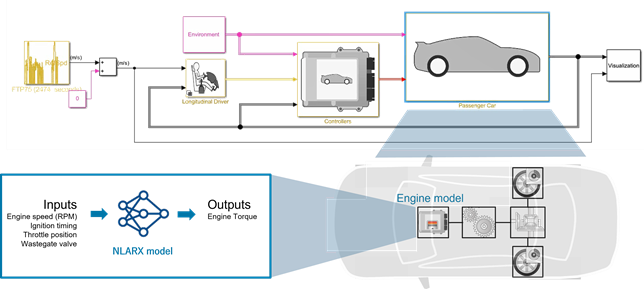

## Data Preparation

Load and display the engine data timetable.

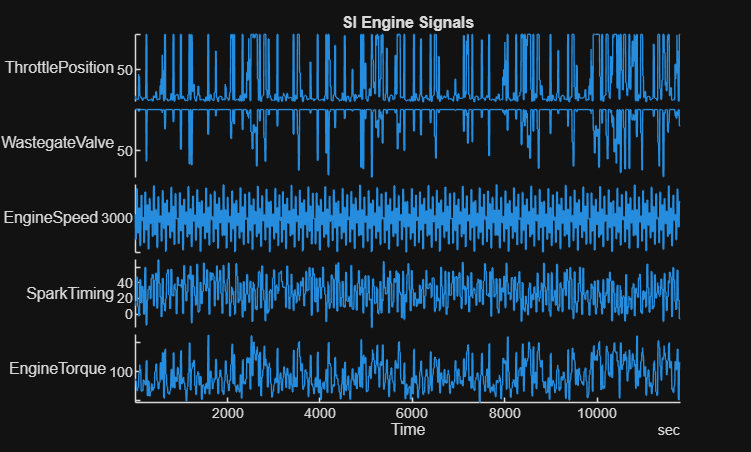

load SIEngineData IOData
stackedplot(IOData)
title('SI Engine Signals')

  The timetable contains over one hundred thousands observations of five variables measured at 10 Hz.

- Throttle position (degrees)

- Wastegate valve area (aperture percentage) 

- Engine speed (RPM)

- Spark timing (degrees)

- Engine torque (N m)

Split the data into estimation (first 60000 data points) and validation (remaining data points) portions.

eData = IOData(1:6e4,:);     % portion used for estimation
vData = IOData(6e4+1:end,:); % portion used for validation

Downsample the training data by a factor of 10. This helps speed up the model training process and also limits the focus of the fit to a lower frequency region. 

% Downsample datasets 10 times
eDataD = idresamp(eData,[1 10]); 
vDataD = idresamp(vData,[1 10]);
eDataD.Properties.TimeStep;


Add inputs and outputs

Inputs = ["ThrottlePosition","WastegateValve","EngineSpeed","SparkTiming"];
Output = "EngineTorque";

Start Reduced Order Modeling App and Select from Imported data and Choose IOData as input. Setup Engine Torque as output

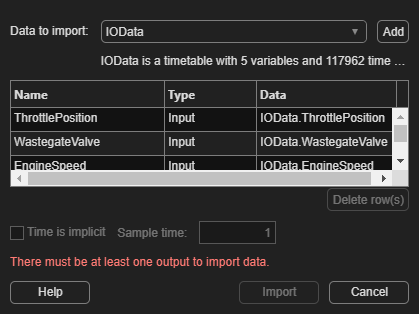

 reducedOrderModeler;

Import the IOData

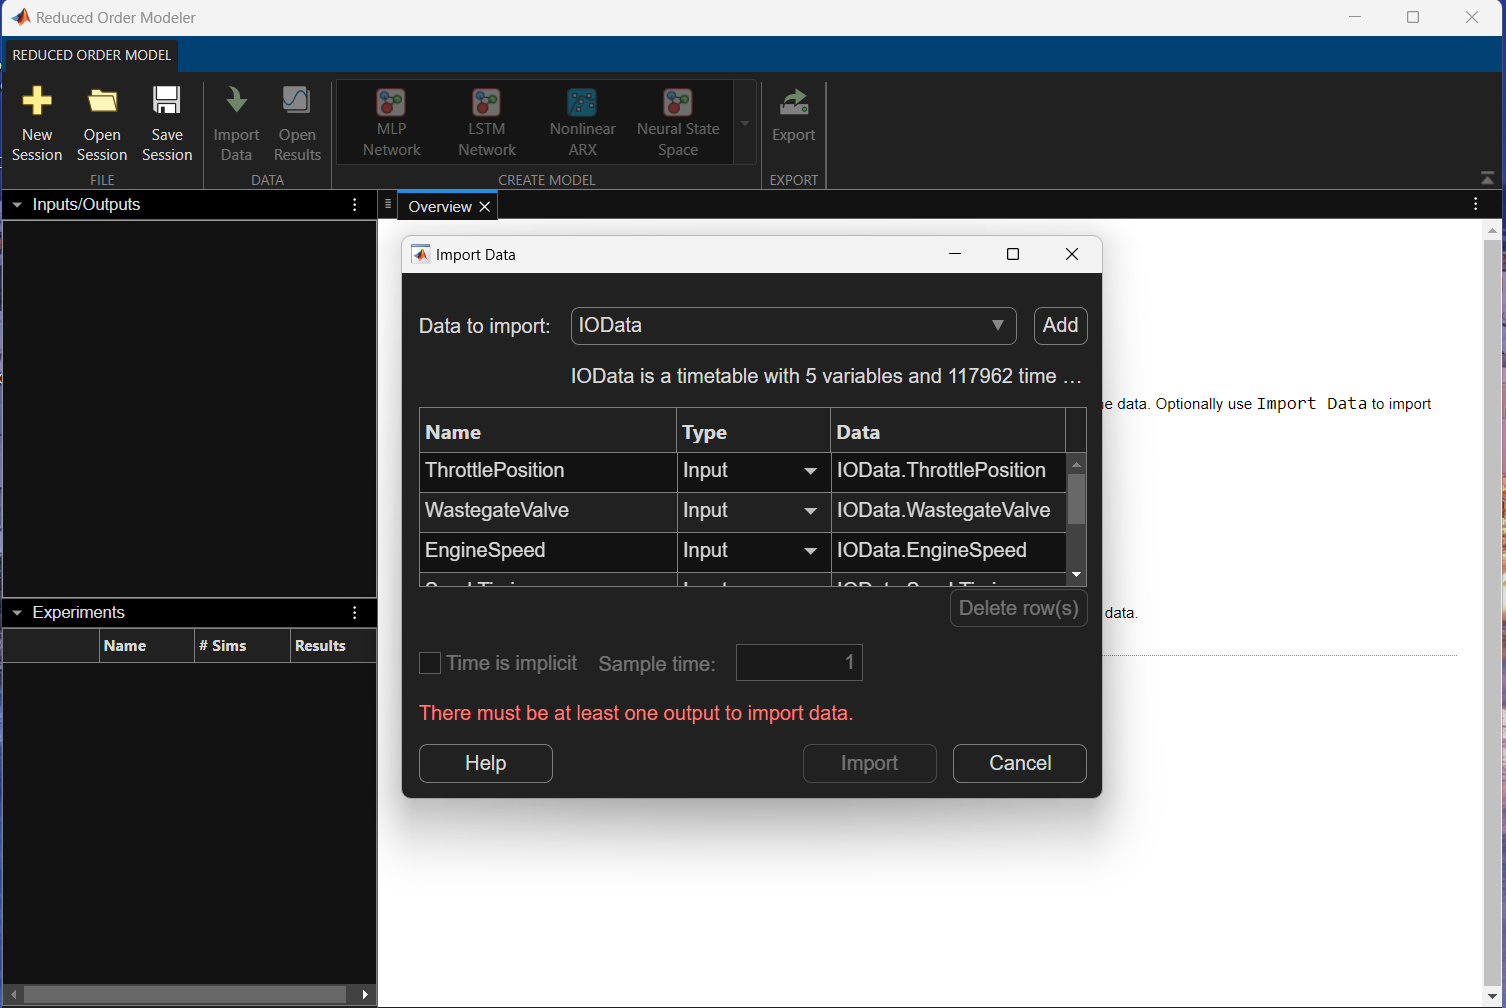

Now Start a New experiment with Bayesian optimization and NLARX Model

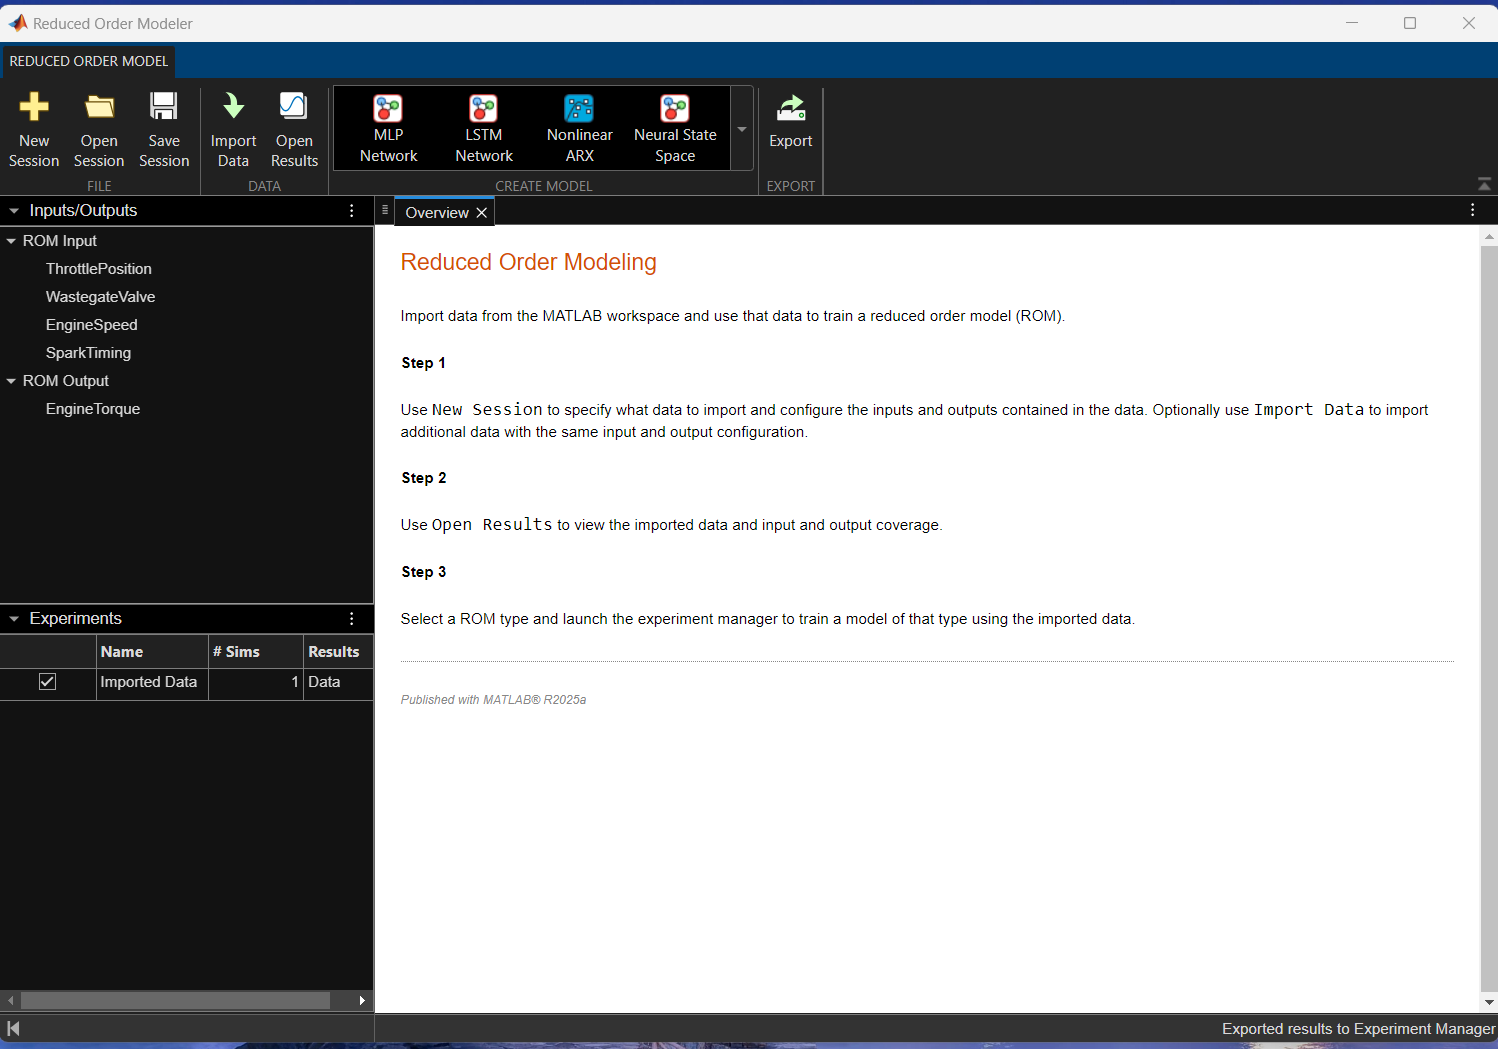

Model is setup and Run the Experiment with NLARX Model

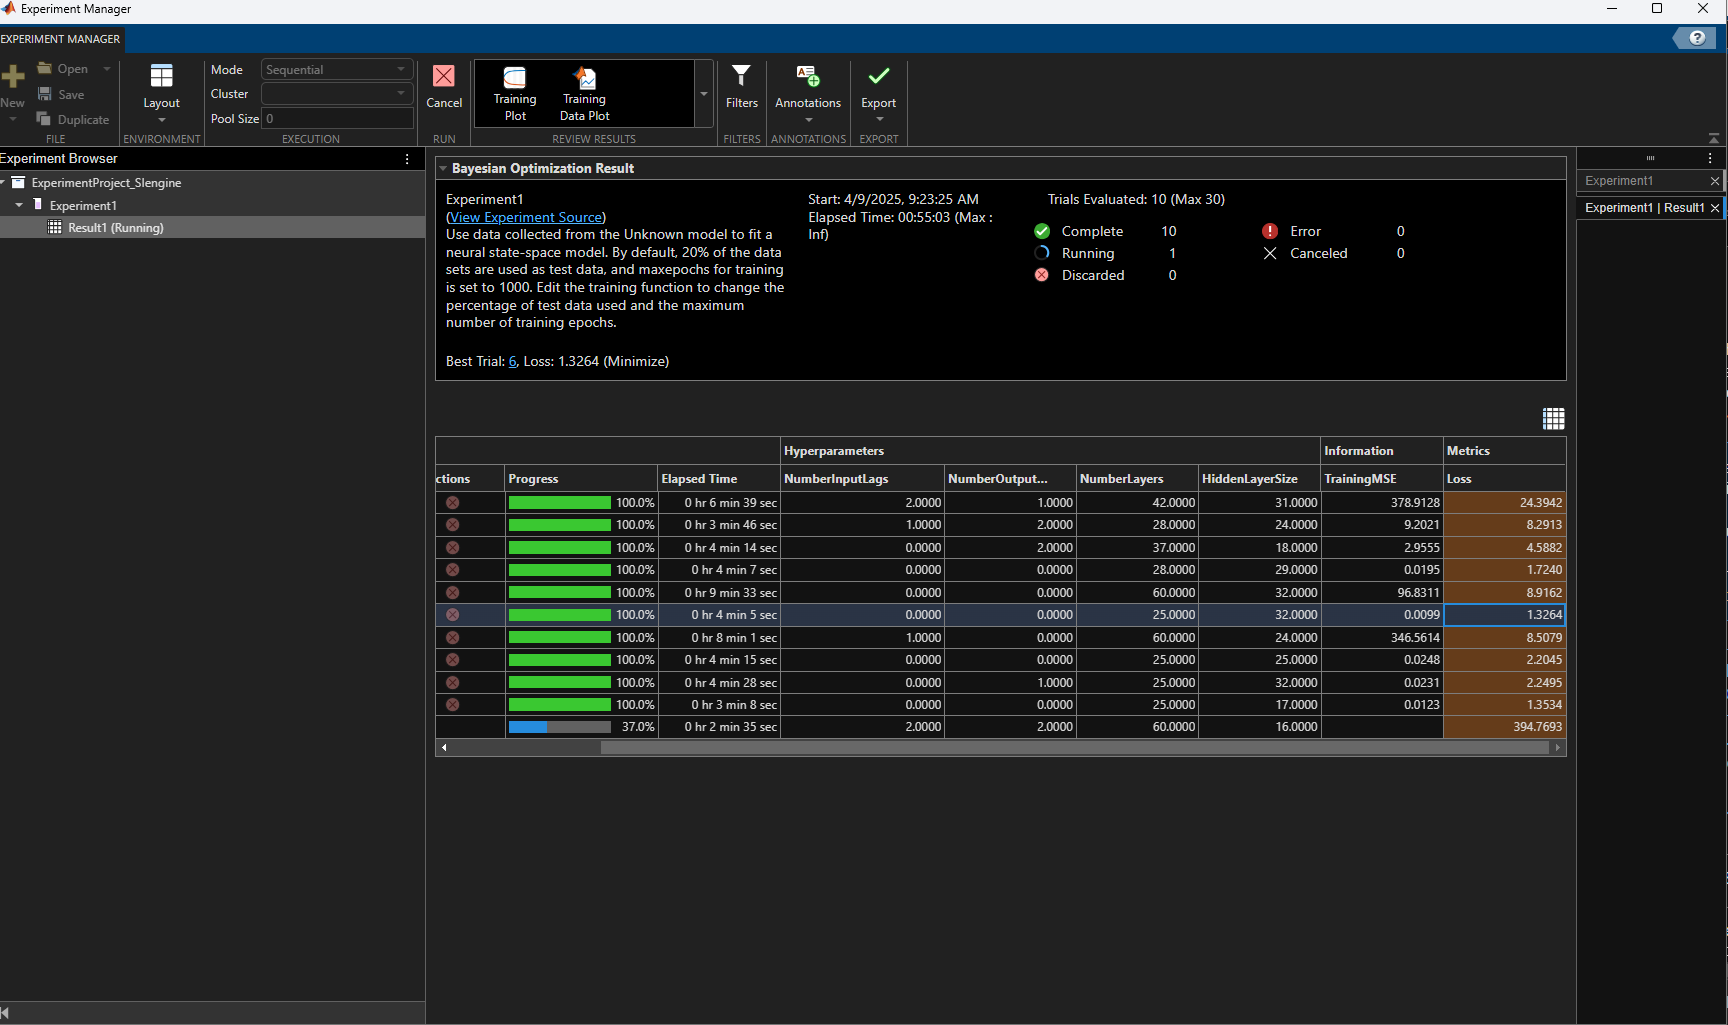

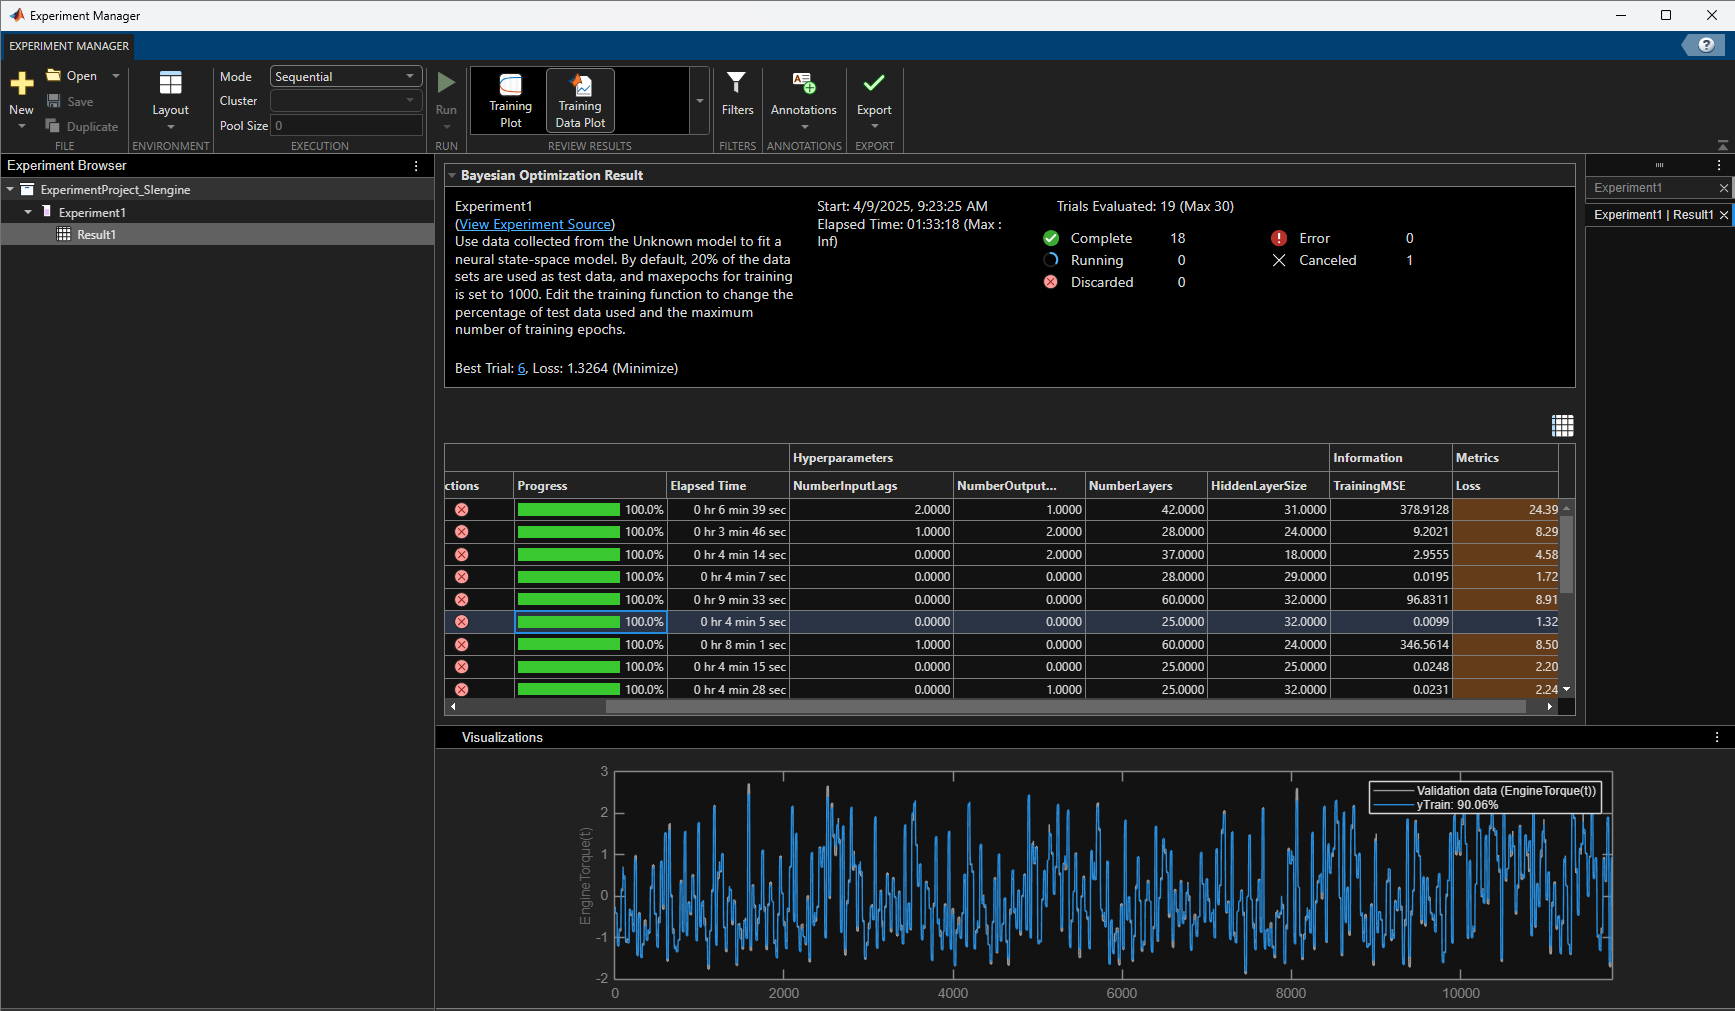

Pick the Best Model and export trainingOutput.

 SigmoidNet=trainingOutput1.NonlinearModel


SigmoidNet =

Nonlinear ARX model with 1 output and 4 inputs
  Inputs: ThrottlePosition, WastegateValve, EngineSpeed, SparkTiming
  Outputs: EngineTorque

Regressors:
  Linear regressors in variables EngineTorque, ThrottlePosition, WastegateValve, EngineSpeed, SparkTiming
  List of all regressors

Output function: Sigmoid network with 29 units
Name: NLARX Model
Sample time: 1 seconds

Status:                                            
Estimated using NLARX on time domain data "zTrain".
Fit to estimation d

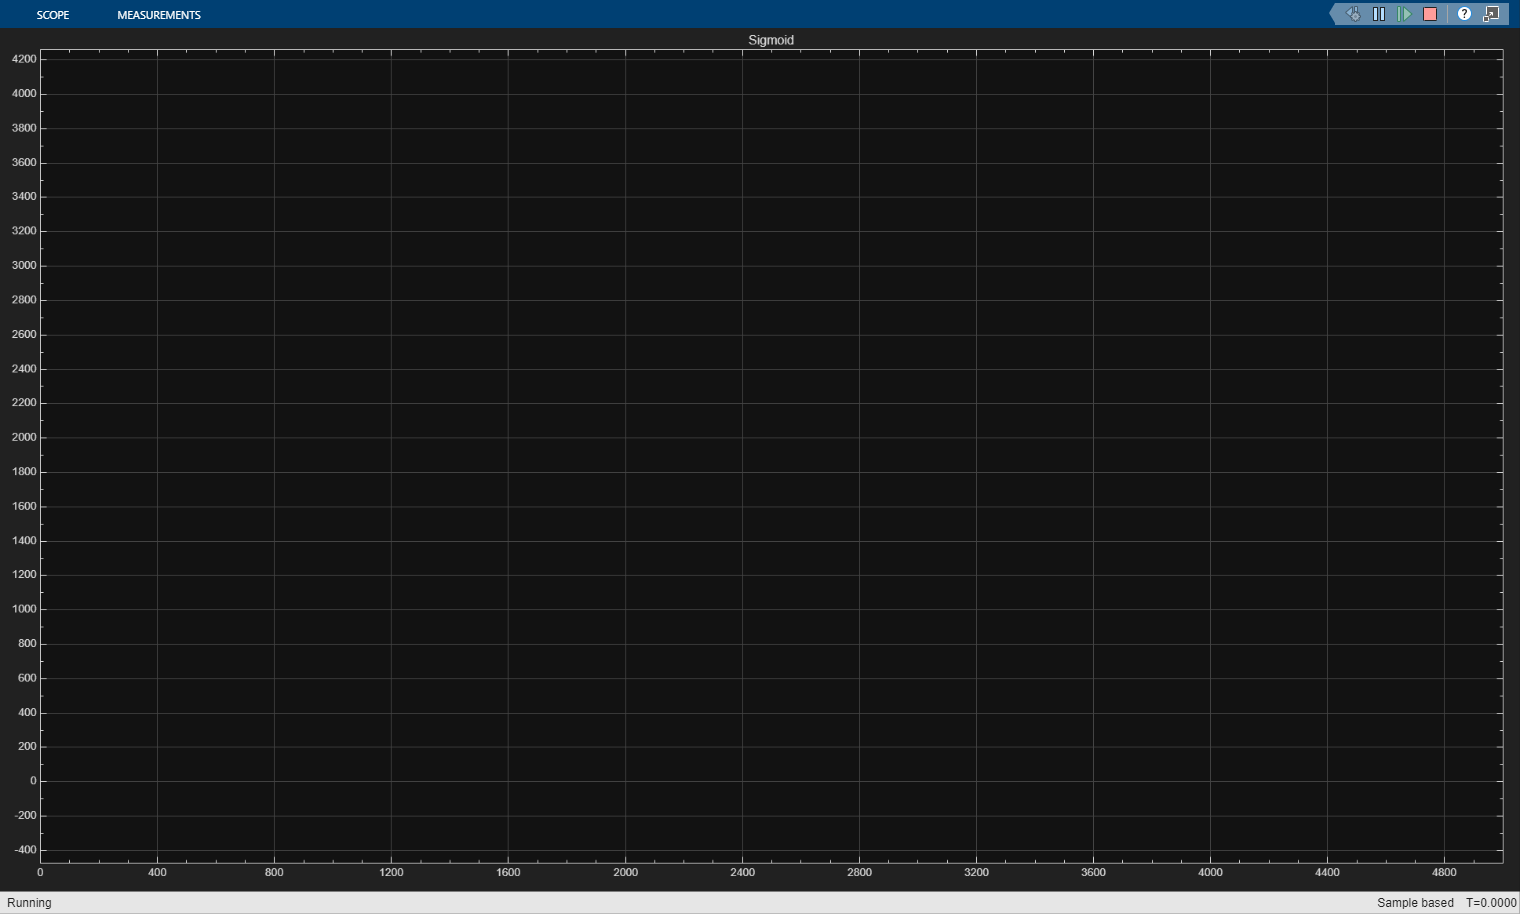

nlarx_ROM